# 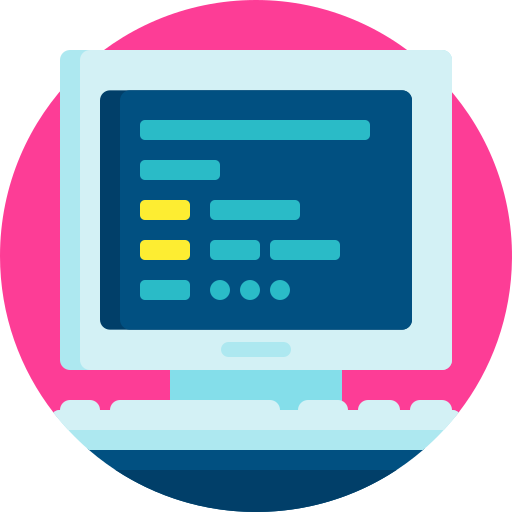

# Assignment 6 - Pose control of a differentially-steered robot

### This Assignment covers Section 5.1-5.2 of the Module A notes.

- This Assignment will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive (or on your PC if you are working on a laptop). 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on right`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (Windows) or CMD+ENTER (macOS).

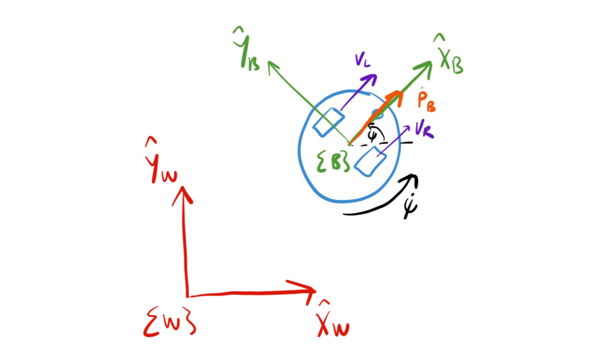

*Figure 1: Representation of differentially-steered robot in frame {W}.*

## Robot setup

We will make use of the Robotic Systems Toolbox to sort out the forward kinematics.

d = 1; %m
r = 0.5; %m
v_max = 15; %m/s
robot = differentialDriveKinematics( TrackWidth=d, WheelRadius=r,WheelSpeedRange=[-v_max,v_max] )

robot =   differentialDriveKinematics with properties:

      VehicleInputs: 'WheelSpeeds'
         TrackWidth: 1
        WheelRadius: 0.5000
    WheelSpeedRange: [-15 15]


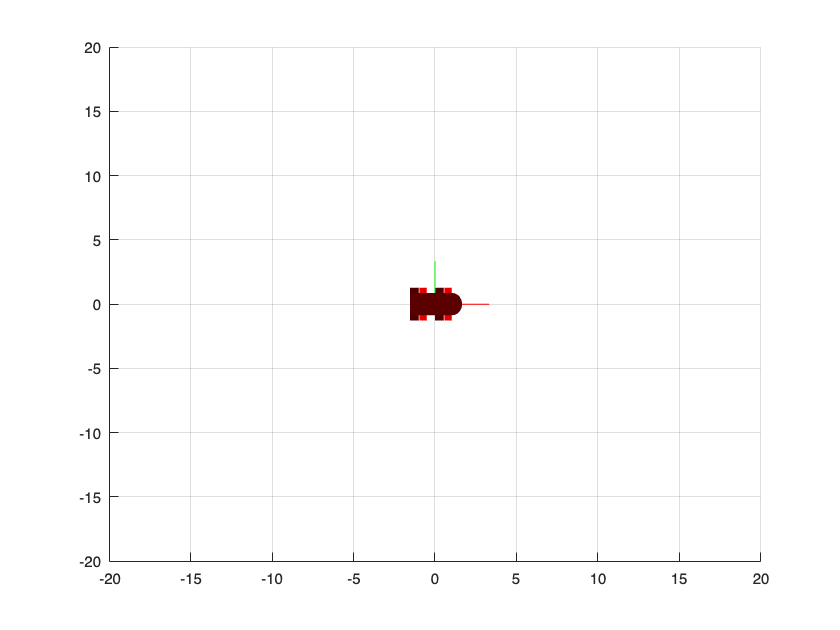


robotPose = [0 0 0]';

figure
plotTrVec = [robotPose(1:2); 0];    %3D position of robot
plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation
plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
light;
axis([-20 20 -20 20])
grid on

Note that we have added maximum wheel velocities of $\pm 15$m/s. This will be important later when we start applying feedback control (our robot will have finite rotational and translational velocity limits).

#### Question 1: Given the parameters above, if the robot was to experience pure translation (no rotation), what is the maximum obtainable linear velocity?

%Add code here
v = 2*v_max/2

v = 15

#### Question 2: Given the parameters above, if the robot was to experience pure rotation (no translation), what is the maximum obtainable angular velocity?

%Add code here
psi_dot_max = 2*v_max/d

psi_dot_max = 30

## Robot forward kinematics

Recall that we can express the forward kinematics of our wheeled robot as


$$\left[\matrix{\dot{p}_x \cr \dot{p}_y \cr \dot{\psi}}\right]=\left[\matrix{\cos (\psi) u_v \cr \sin(\psi)u_v \cr u_\psi }\right],$$


where $u_v=\frac{r}{2}(\phi_L+\phi_R)$, and $u_\psi=\frac{r}{d}(\phi_R-\phi_L)$. $\{u_v,u_\psi\}$ are our high-level control actions (linear and rotation velocity signals in the body-frame) that we will manipulate. 

Express the relationship above, between $\{u_v,u_\psi\}$ and $\{\phi_L,\phi_R\}$ in the form

$\left[\matrix{u_v \cr u_\psi}\right]={\bf A} \left[\matrix{\phi_L \cr \phi_R}\right]$.

#### Question 3: Find ${\bf A}^{-1}$, the matrix that maps the input signals, $\{u_v,u_\psi\}$, to the desired wheel velocities, $\{\phi_L,\phi_R\}$. 

*Hint: use the symbolic toolbox.*

%Add code here
syms r d u_v u_psi phiL phiR real
A = [r/2 r/2; -r/d r/d];
invA = inv(A)

$$invA = \left(\begin{array}{cc} \frac{1}{r} & -\frac{d}{2\,r}\\ \frac{1}{r} & \frac{d}{2\,r} \end{array}\right)$$

We will use this later in the Assignment when we need to map our control signals to the wheel speeds.

## Position error 

Lets assume that ${^W{\bf p}^*}=[10~10~0]^T$

p_des = [10 10 0]';

Update your previous figure to include this point. Indicate it with a red circle (see [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html#btzptin) if need be).

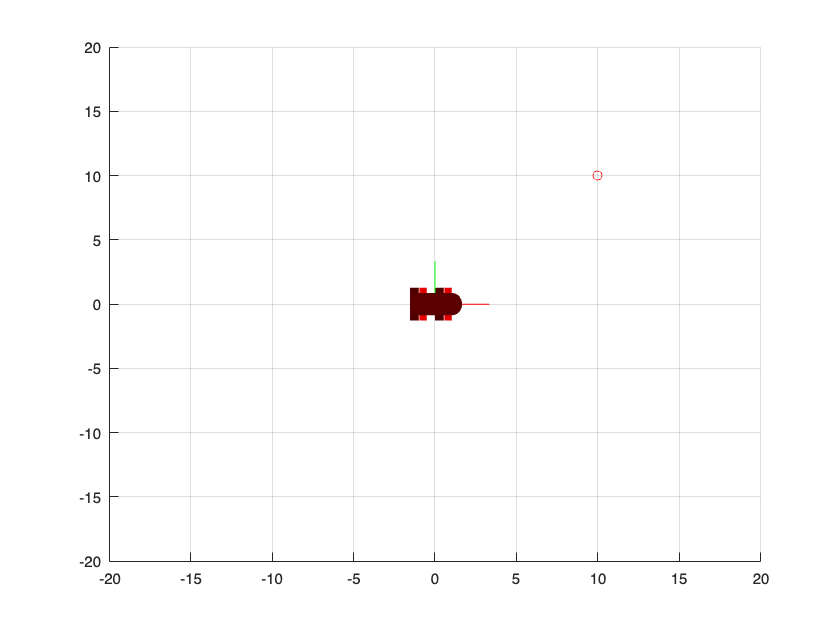

%Add code here
figure,clf,hold on
plotTrVec = [robotPose(1:2); 0];    %3D position of robot
plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation
plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
light;

p_des = [10 10 0]';
plot(p_des(1),p_des(2),'ro')

axis([-20 20 -20 20])
grid on

### Inertial-frame position error

The inertial-frame position error is simply the difference between the current position, ${^W{\bf p}}$, and desired position, ${^W{\bf p}^*}$,

${^W{\bf e}_p}={^W{\bf p}^*}-{^W{\bf p}}$.

Using our current position, we can determine the inertial-frame position error 

p = [robotPose(1:2); 0]

p =      0
     0
     0


e_p_wf = p_des - p

e_p_wf =     10
    10
     0


So our robot is required to move $10$ metres in the positive $\hat{\bf x}_W$-axis and $10$ metres in the positive $\hat{\bf y}_W$-axis direction. Ensure that you are comfortable with this geometry before moving on.

### Body-frame position error

If we know our inertial-frame position error and current orientation, $\psi$, we can derive the corresponding body-frame position error using

${^B{\bf e}_p}={^B{\bf R}_W}{^W{\bf e}_p}={^B{\bf R}_W}\left({^W{\bf p}^*}-{^W{\bf p}})$,

where ${^B{\bf R}_W$ is the rotation matrix that encodes the orientation of frame $\{W\}$ with respect to frame $\{B\}$.

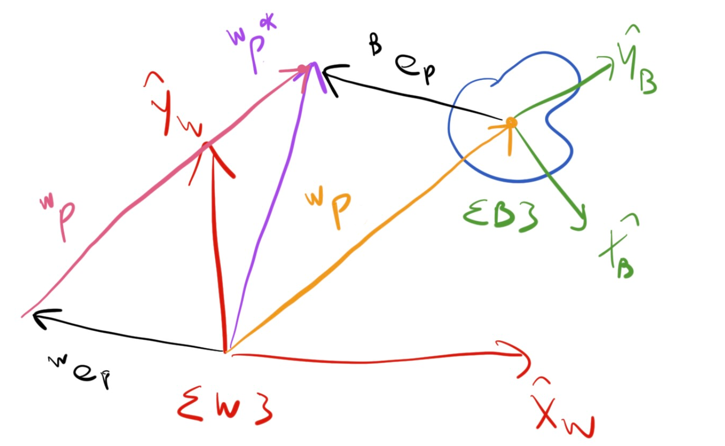

*Figure 2: Vector representation of relationship between inertial-frame and body-frame position error.*

Using the current pose and desired position, determine the body-frame error.

%Add code here
psi = robotPose(3);
R_b2w = [cos(psi) -sin(psi) 0;
    sin(psi)  cos(psi) 0;
    0          0       1];
e_p_bf = R_b2w'*e_p_wf

e_p_bf =     10
    10
     0


What you should find is that the inertial-frame and body-frame position errors are equivalent for the particular configuration (when $\psi=0$).

#### Question 4: Determine the body-frame position error if the orientation is $\psi=pi/2$.

*Hint: visualise the robot in this pose to ensure that the errors makes physical sense.*

%Add code here
psi = pi/2;
R_b2w = [cos(psi) -sin(psi) 0;
    sin(psi)  cos(psi) 0;
    0          0       1];
e_p_bf = R_b2w'*e_p_wf

e_p_bf =     10
   -10
     0


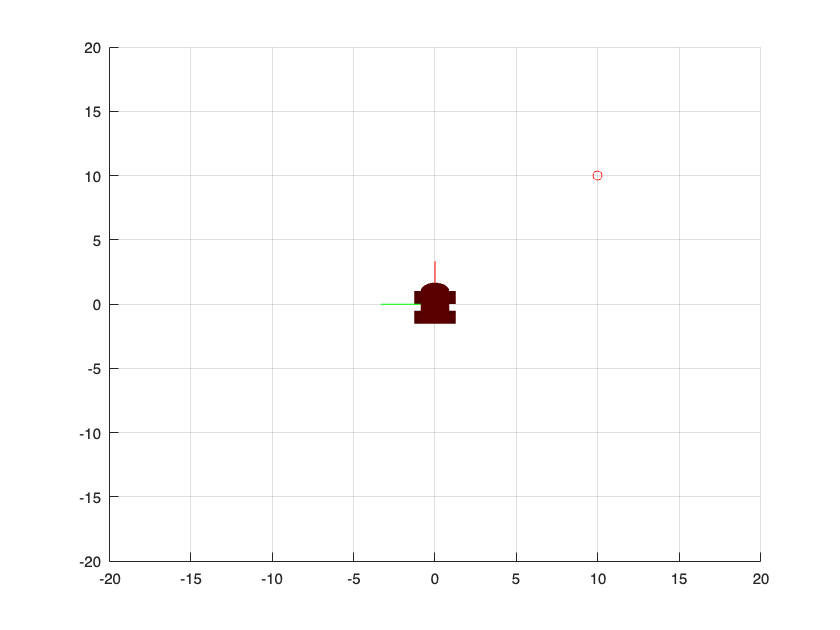


%Pose visualisation
robotPose = [0 0 pi/2]';
figure,clf,hold on
plotTrVec = [robotPose(1:2); 0];    %3D position of robot
plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation
plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
light;

p_des = [10 10 0]';
plot(p_des(1),p_des(2),'ro')

axis([-20 20 -20 20])
grid on

Ensure that you are comfortable with the position errors in both frames. Specifically, when they do and do not match.

## Orientation error

In the case of the differentially-steered robot, we are only concerned with a single rotation angle, $\psi$. Similar to the inertial-frame position error, we can define the inertial-frame orientation error as

${^W{e}_\psi}=\psi^*-\psi$,

where $\psi^*$ is the desired orientation. Given that our wheeled robot can only produce translational velocities in the $\hat{\bf x}_B$ axis, the desired orientation is equivalent to when $\hat{\bf x}_B$ points in the direction of the desired position, ${^W{\bf p}^*}$. This is described mathematically as

$\psi^*=\tan^{-1}\left(\frac{{e_p}_y}{{e_p}_x}\right)$,

where ${e_p}_x$ and ${e_p}_y}$ are the position errors in the $\hat{\bf x}_W$ and $\hat{\bf y}_W$ axes, respectively.

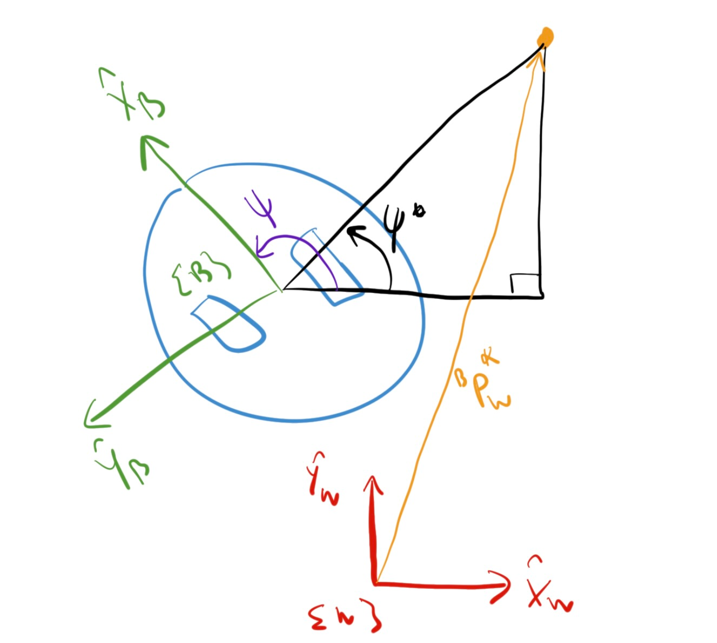

*Figure 3: Vector representation of how *$\psi^*$ is formulated.

Importantly, we must use the `atan2 `function instead of `atan `in general, as the desired orientation will exist in the interval of $\psi^* \in [-\pi,\pi]$, but `atan `only returns angles in the right-half plane quadrants: $[-\pi/2,\pi/2]$.

#### Question 5: Using the initial configuration and desired position from before, determine $\psi^*$.

%Add code here
psi_des = atan2(e_p_wf(2),e_p_wf(1))*180/pi

psi_des = 45

Ensure that your answer makes sense based on the robot's current configuration and target destination.

## Orientation control

Given that we can specify a desired orientation that is dependant on the inertial-frame position errors, the next step is to devise a control scheme so that the robot is automatically reoriented correctly. Because $u_\psi$ is the control action that relates to our angular velocity, it makes sense to affect change here. We will define the control law of

$u_\psi=k_\psi(\psi^*-\psi) = k_\psi\left(\tan^{-1}\frac{{e_p}_y}{{e_p}_x}-\psi\right)$,

where $k_\psi>0$ is our proportional controller. Based on the structure above, an angular velocity will be commanded until such time that the actual orientation is equal to that of the desired orientation (assuming there are no input disturbances).

Using the skeleton structure below, add the relevant code to orient the robot such that it points towards the target point. 

- You will need to select an appropriate proportional gain, `k_psi`. 

- Do not command any translational velocity. 

- Use the prescribed variable names. 

- The robot must achieve an orientation error of $|e_\psi|<0.01$ degrees within three seconds.

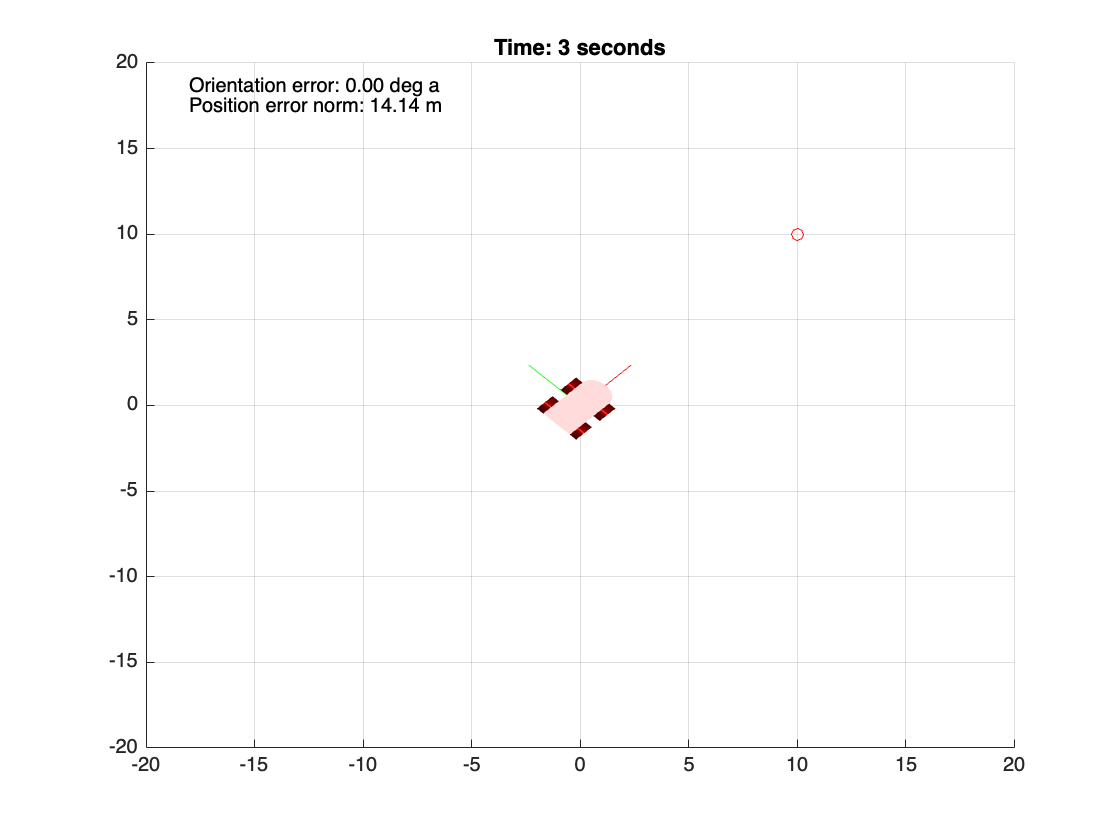

d = 1; %m
r = 0.5; %m
dT = 0.05;
timer = rateControl(1/dT);

k_psi = 5;
p_des = [10 10]';

robotPose = [0 0 0]';

t = 0;
for i=1:(3/dT)  %run the simulation for a time equivalent to 3 seconds
    figure(1),clf,hold on

    u_v = 0;
    e_p_wf = p_des(1:2)-robotPose(1:2);

    psi = robotPose(3);
    psi_des = atan2(e_p_wf(2),e_p_wf(1));
    e_psi = psi_des-psi;
    u_psi = k_psi*e_psi;

    phi_des = eval(invA)*[u_v,u_psi]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    plotTrVec = [robotPose(1:2); 0];    %extract 2D position of robot
    plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    axis([-20 20 -20 20]),grid on
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
    light;

    p_des = [10 10 0]';
    plot(p_des(1),p_des(2),'ro')

    t = t+dT;
    title(['Time: ',num2str( t ), ' seconds'])
    text(-18,18,{['Orientation error: ',num2str( e_psi*180/pi,'%.2f' ), ' deg a'], ...
                 ['Position error norm: ',num2str( norm(e_p_wf),'%.2f' ), ' m']})

    drawnow
    waitfor(timer);
end

#### Question 6: Upload a .gif or .mp4 of the simulation.

*Hint: use the Export Animation button, found at the bottom right of the figure (applicable to MATLAB R2021b+).*

## Position control

The input signal of $u_v$ is used to command forward/reverse velocities in the $\hat{\bf x}_B$-axis. Similar to how we structured our orientation control law to command rotational velocities based on the orientation error, we can adjust $u_v$ using position errors. Importantly, we need to make use of the position error in the $\hat{\bf x}_B$-axis, as $u_v$ can only affect change in that axis. With reference to our previous description of the body-frame position error, the error in the $\hat{\bf x}_B$-axis is defined as

${^Be_x}=\cos(\psi){^We_x}+\sin(\psi){^We_y}$.

The proposed control law follows as


$$\begin{array}{ll}
u_v &=k_v{^Be_x}, \\ 
&=k_v\left( \cos(\psi) 
{^We_x}+\sin(\psi){^We_y} \right),
\end{array}$$


where $k_v>0$ is the proportional gain. We will use the inertial-frame error norm of


$$||{\bf e}_p||=\sqrt{{e_p}_x^2+{e_p}_y^2}$$


to quantify how close to the target point we are.

Adjust your code so that the position controller is also activated during the simulation.

- You will need to select an appropriate combination of `k_psi `and `k_v`.

- Ensure that a position error norm of $||{\bf e}_p||<0.2$ metres is obtained within the $3$ second simulation.

- The end orientation error of the robot is inconsequential for this objective.

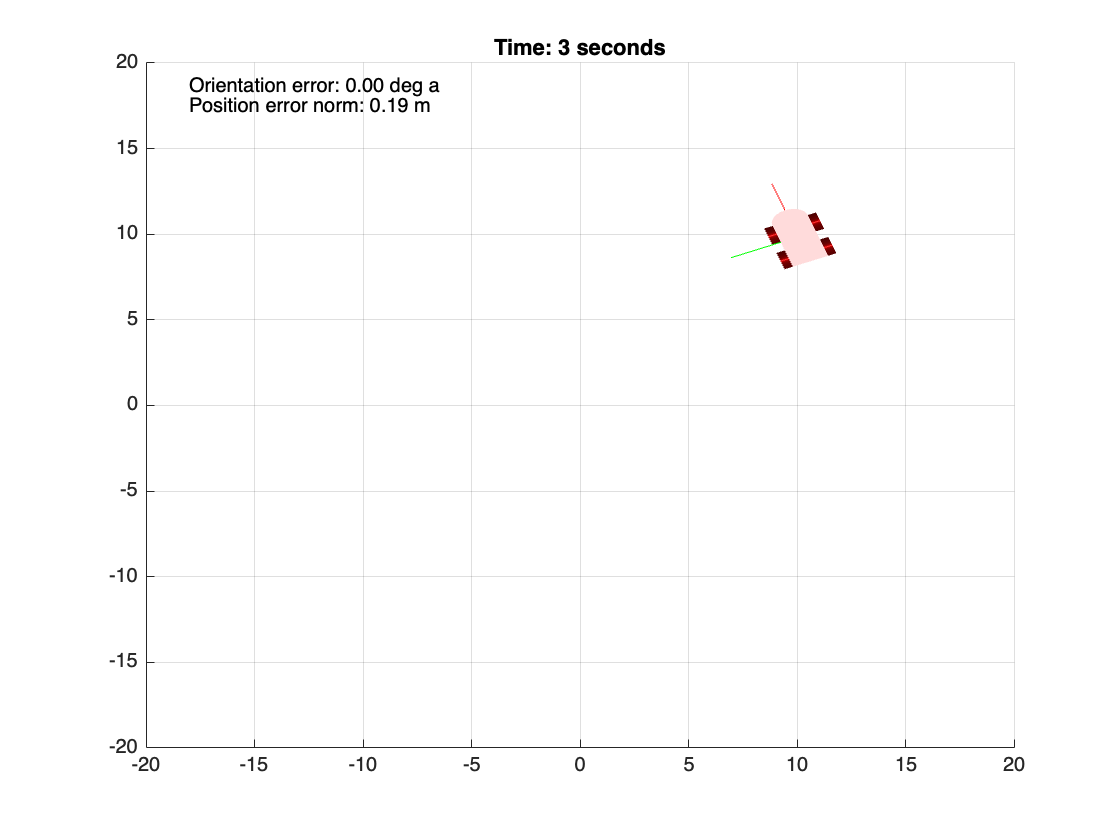

d = 1; %m
r = 0.5; %m
dT = 0.05;
timer = rateControl(1/dT);

k_psi = 37;
k_v = 3.1;
% p_des = [10 10]';

robotPose = [0 0 0]';

t = 0;
for i=1:(3/dT)  %run the simulation for a time equivalent to 3 seconds
    figure(1),clf,hold on

    e_p_wf = p_des(1:2)-robotPose(1:2);

    psi = robotPose(3);
    
%     psi_des = unwrap(psi_des);
%     if( psi_des<0 ), psi_des=psi_des+2*pi; end
    
   
    if( norm(e_p_wf)>0.2 )
        psi_des = atan2(e_p_wf(2),e_p_wf(1));
    end

    e_psi = psi_des-psi;
    u_psi = k_psi*e_psi;

    u_v = k_v*( cos(psi)*e_p_wf(1)+sin(psi)*e_p_wf(2) );

    phi_des = eval(invA)*[u_v,u_psi]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    plotTrVec = [robotPose(1:2); 0];    %extract 2D position of robot
    plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    axis([-20 20 -20 20]),grid on
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
    light;

    p_des = [10 10 0]';
    plot(p_des(1),p_des(2),'ro')

    t = t+dT;
    title(['Time: ',num2str( t ), ' seconds'])
    text(-18,18,{['Orientation error: ',num2str( e_psi*180/pi,'%.2f' ), ' deg a'], ...
                 ['Position error norm: ',num2str( norm(e_p_wf),'%.2f' ), ' m']})

    drawnow
    waitfor(timer);
end

#### Question 7: Upload a .gif or .mp4 of the simulation.

What you should find is that sharing the control bandwidth allocation between the orientation and position feedback loop is not trivial. This is because the maximum wheel speeds of $v_{max}=\pm 15$ means that you cannot simultaneously turn and translate quickly — there is a trade-off between the two. Additionally, when $||{\bf e}_p||$ gets small, the approach of deriving the desired orientation using $\psi^*=\tan^{-1}\left(\frac{{e_p}_y}{{e_p}_x}\right)$ becomes erratic (small changes in the error results in large angle changes).

An alternative approach is to first set the orientation such that the robot is pointing towards the target point, and then subsequently only command a translational velocity. In this way, the two control loops become completely decoupled and selection of the two gains becomes a lot easier. Additionally, this removes the issue of having to constantly define a new desired orientation when the error gets small.

- Adjust your code from before so that the position controller only becomes active when the orientation error is less than $|e_\psi|<0.01$ degrees.

- Ensure that a position error norm of $||{\bf e}_p||<0.05$ metres is obtained within the $3$ second simulation.

- Use $\psi^*=\tan^{-1}\left(\frac{{e_p}_y}{{e_p}_x}\right)$ to set the initial desired orientation, but then change to a constant desired orientation (logically chosen) when $||{\bf e}_p||<0.2$.

- The end orientation error of the robot is inconsequential for this objective.

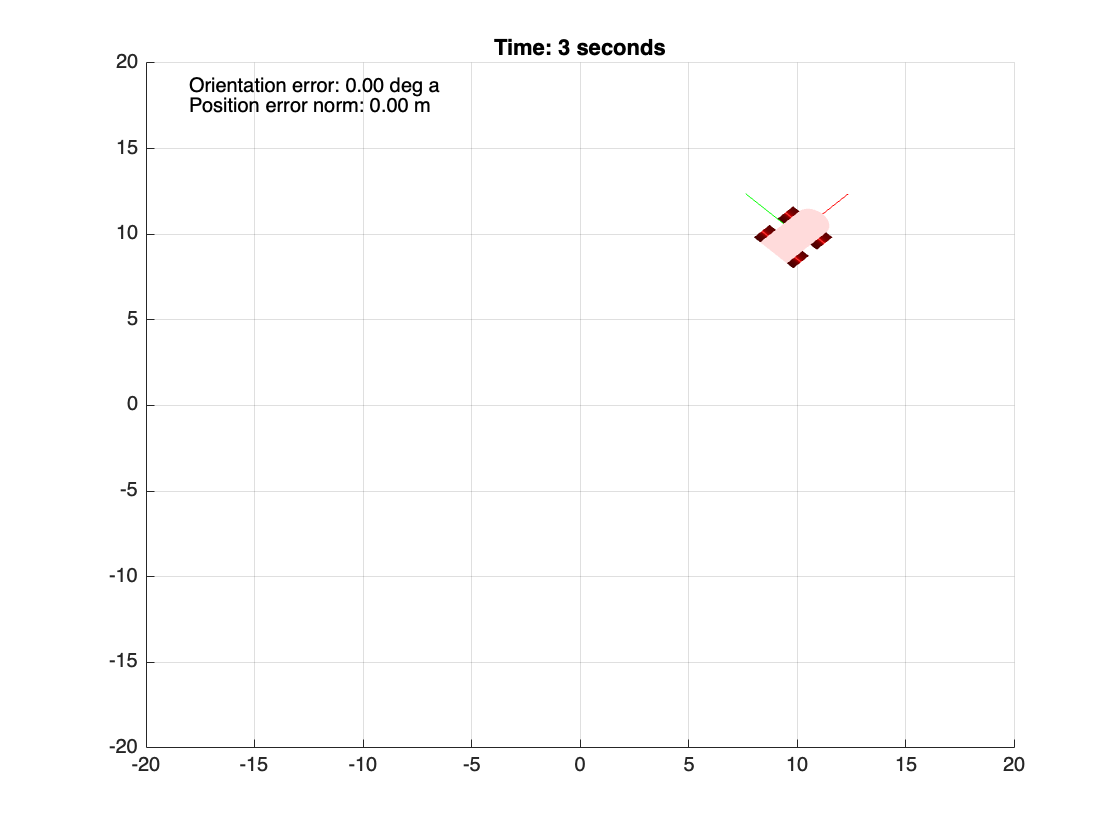

d = 1; %m
r = 0.5; %m
dT = 0.05;
timer = rateControl(1/dT);

k_psi = 10;
k_v = 24;
% p_des = [10 10]';

robotPose = [0 0 0]';

psi_des_initial = atan2(p_des(2)-robotPose(2),p_des(1)-robotPose(1));

t = 0;
for i=1:(3/dT)  %run the simulation for a time equivalent to 3 seconds
    figure(1),clf,hold on

    e_p_wf = p_des(1:2)-robotPose(1:2);

    psi = robotPose(3);
    psi_des = psi_des_initial;

    e_psi = psi_des-psi;
    u_psi = k_psi*e_psi;

    if ( abs(e_psi)<0.01*pi/180 )
        u_v = k_v*( cos(psi)*e_p_wf(1)+sin(psi)*e_p_wf(2) );
    else
        u_v = 0;
    end

    phi_des = eval(invA)*[u_v,u_psi]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    plotTrVec = [robotPose(1:2); 0];    %extract 2D position of robot
    plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    axis([-20 20 -20 20]),grid on
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
    light;

    p_des = [10 10 0]';
    plot(p_des(1),p_des(2),'ro')

    t = t+dT;
    title(['Time: ',num2str( t ), ' seconds'])
    text(-18,18,{['Orientation error: ',num2str( e_psi*180/pi,'%.2f' ), ' deg a'], ...
                 ['Position error norm: ',num2str( norm(e_p_wf),'%.2f' ), ' m']})

    drawnow
    waitfor(timer);
end

#### Question 8: Upload a .gif or .mp4 of the simulation.

The target pose used in the previous questions has not explicitly specified a desired orientation. As you should have seen, the final orientation is dictated by the final angle of approach of the target position. 

- Adjust your code from before so that the robot (approximately) achieves a final pose of $\xi=[10~10~\pi/2]^T$ within 3 seconds.

- Ensure that a position error norm of $||{\bf e}_p||<0.05$ metres is obtained within the 3 second simulation.

- The final orientation error must be less than $|e_\psi|<0.01$ degrees.

*Hint: turning on the spot is allowed!*

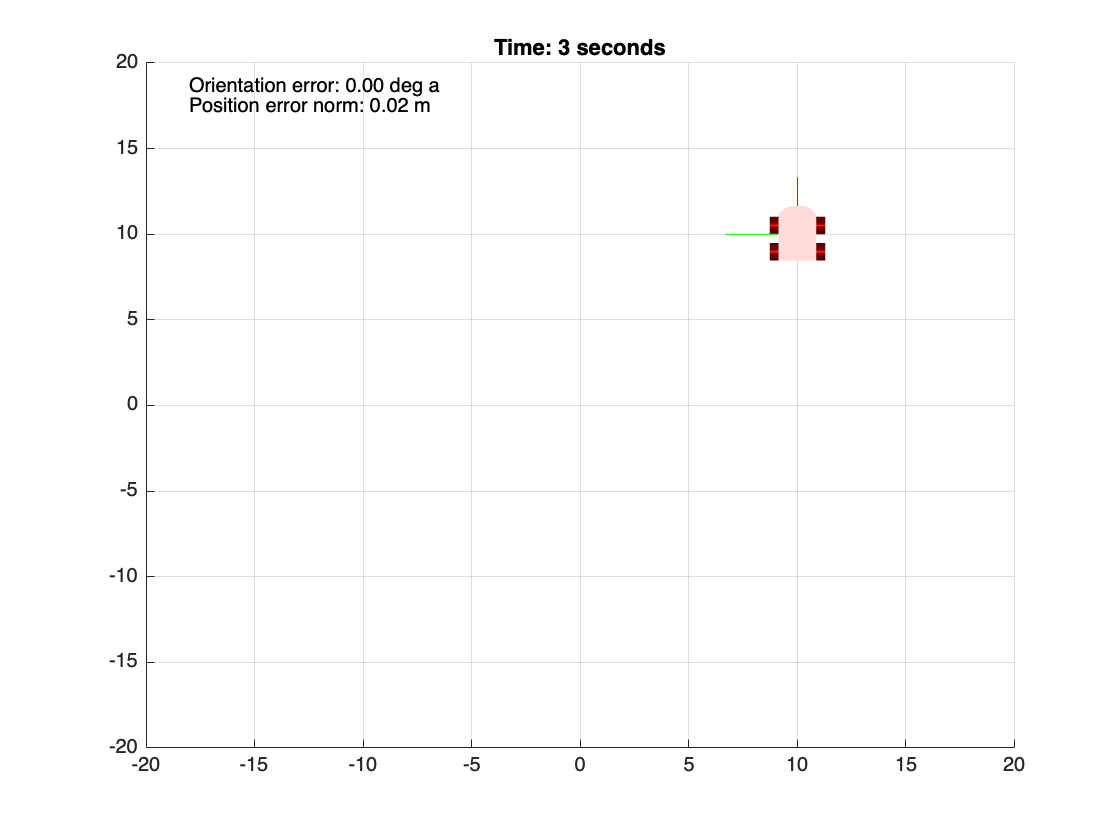

d = 1; %m
r = 0.5; %m
dT = 0.05;
timer = rateControl(1/dT);

k_psi = 29;
k_v = 31;
% p_des = [10 10]';

robotPose = [0 0 0]';
psi_des_initial = atan2(p_des(2)-robotPose(2),p_des(1)-robotPose(1));
psi_des_final = pi/2;

t = 0;
for i=1:(3/dT)  %run the simulation for a time equivalent to 3 seconds
    figure(1),clf,hold on

    e_p_wf = p_des(1:2)-robotPose(1:2);

    psi = robotPose(3);
    
    if( norm(e_p_wf)>0.05 )
%         psi_des = atan2(e_p(2),e_p(1));
        psi_des = psi_des_initial;
    else
        psi_des = psi_des_final;
    end

    e_psi = psi_des-psi;

    u_psi = k_psi*e_psi;

    if ( abs(e_psi)<0.01*pi/180 )
        u_v = k_v*( cos(psi)*e_p_wf(1)+sin(psi)*e_p_wf(2) );
    else
        u_v = 0;
    end

    phi_des = eval(invA)*[u_v,u_psi]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    plotTrVec = [robotPose(1:2); 0];    %extract 2D position of robot
    plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    axis([-20 20 -20 20]),grid on
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
    light;

    p_des = [10 10 0]';
    plot(p_des(1),p_des(2),'ro')

    t = t+dT;
    title(['Time: ',num2str( t ), ' seconds'])
    text(-18,18,{['Orientation error: ',num2str( e_psi*180/pi,'%.2f' ), ' deg a'], ...
                 ['Position error norm: ',num2str( norm(e_p_wf),'%.2f' ), ' m']})

    drawnow
    waitfor(timer);
end

#### Question 9: Upload a .gif or .mp4 of the simulation.

#### Question 10: Upload your .mlx file.